clear all, close all, clc

## Prob-3.5a

Let's break down the system like this-

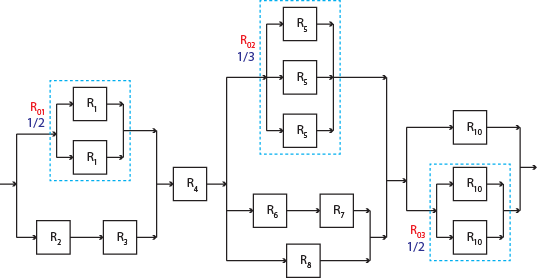

Let's reduce the system with redundancies


$$R_{M\left|N\right.} {\left(t\right)}=\sum_{n,M}^N {\left(\begin{array}{c}
N\\
n
\end{array}\right)}{{\left[R{\left(t\right)}\right]}}^n {{\left(1-R{\left(t\right)}\right)}}^{N-n}$$


syms R1
N = 2; M = 1;
R_o1 = 0;           % initializing
for n = M:1:N
        C = nchoosek(N,n);      % combination
    R_n(n) = C *R1^n *(1 - R1)^(N-n);
    R_o1 = R_o1 + R_n(n); 
end 
R_o1

$$R\_o1 = {R_{1}}^{2}-2\,R_{1}\,\left(R_{1}-1\right)$$

Then, let's find the reliability of system R_02

syms R5
N = 3; M = 1;
R_o2 = 0;           % initializing
for n = M:1:N
        C = nchoosek(N,n);      % combination
    R_n(n) = C *R5^n *(1 - R5)^(N-n);
    R_o2 = R_o2 + R_n(n); 
end 
R_o2

$$R\_o2 = {R_{5}}^{3}+3\,R_{5}\,{\left(R_{5}-1\right)}^{2}-3\,{R_{5}}^{2}\,\left(R_{5}-1\right)$$

And then, R_03

syms R10
N = 2; M = 1;
R_o3 = 0;           % initializing
for n = M:1:N
        C = nchoosek(N,n);      % combination
    R_n(n) = C *R10^n *(1 - R10)^(N-n);
    R_o3 = R_o3 + R_n(n); 
end 
R_o3

$$R\_o3 = {R_{10}}^{2}-2\,R_{10}\,\left(R_{10}-1\right)$$

So, the system becomes-

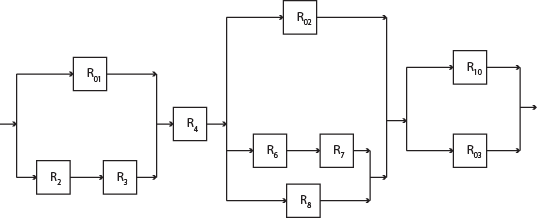

Then, let's reduce the following systems

syms R2 R3 R4 R6 R7 R8 R9
R_23 = R2 *R3

$$R\_23 = R_{2}\,R_{3}$$


R_67 = R6 *R7;
R_678 = R_67 + R8 - R_67 *R8

$$R\_678 = R_{8}+R_{6}\,R_{7}-R_{6}\,R_{7}\,R_{8}$$

So, this systems redues like follows-

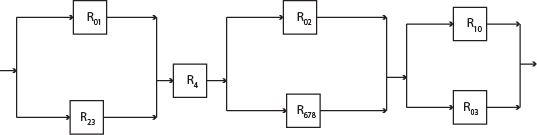

Let's further reduce it like this-

R_o1_23 = R_o1 + R_23 - R_o1 *R_23

$$R\_o1\_23 = R_{2}\,R_{3}-2\,R_{1}\,\left(R_{1}-1\right)+{R_{1}}^{2}+R_{2}\,R_{3}\,\left(2\,R_{1}\,\left(R_{1}-1\right)-{R_{1}}^{2}\right)$$

R4 = R4;
R_o2_678 = R_o2 + R_678 - R_o2 *R_678

$$R\_o2\_678 = R_{8}+R_{6}\,R_{7}+{R_{5}}^{3}+3\,R_{5}\,{\left(R_{5}-1\right)}^{2}-3\,{R_{5}}^{2}\,\left(R_{5}-1\right)-\left(R_{8}+R_{6}\,R_{7}-R_{6}\,R_{7}\,R_{8}\right)\,\left({R_{5}}^{3}+3\,R_{5}\,{\left(R_{5}-1\right)}^{2}-3\,{R_{5}}^{2}\,\left(R_{5}-1\right)\right)-R_{6}\,R_{7}\,R_{8}$$

R_o3_9 = R_o3 + R9 - R_o3 *R9

$$R\_o3\_9 = R_{9}-2\,R_{10}\,\left(R_{10}-1\right)+R_{9}\,\left(2\,R_{10}\,\left(R_{10}-1\right)-{R_{10}}^{2}\right)+{R_{10}}^{2}$$

Hereby, the eventual system becomes-

R_sy = R_o1_23 *R4 *R_o2_678 *R_o3_9;

(Derived) 

## Prob-3.5b

The system we found from earlier part, let's put the following values

syms R
[R2 R3 R4 R6 R7 R8 R9] = deal(R);        % inputs same value @ each variable

And we  had earlier-

R_sy = R_o1_23 *R4 *R_o2_678 *R_o3_9;

Let's find an expression i.t.o R, R1, R5, and R10

R_sy = eval(R_sy)

$$R\_sy = \begin{array}{l} R\,\left(R^{2}-\sigma_{4}+{R_{1}}^{2}+R^{2}\,\left(\sigma_{4}-{R_{1}}^{2}\right)\right)\,\left(R-\sigma_{3}+R\,\left(\sigma_{3}-{R_{10}}^{2}\right)+{R_{10}}^{2}\right)\,\left(R-\left(-R^{3}+R^{2}+R\right)\,\left({R_{5}}^{3}+\sigma_{2}-\sigma_{1}\right)+R^{2}-R^{3}+{R_{5}}^{3}+\sigma_{2}-\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}=3\,{R_{5}}^{2}\,\left(R_{5}-1\right)\\ \sigma_{2}=3\,R_{5}\,{\left(R_{5}-1\right)}^{2}\\ \sigma_{3}=2\,R_{10}\,\left(R_{10}-1\right)\\ \sigma_{4}=2\,R_{1}\,\left(R_{1}-1\right) \end{array}$$

Now, let's put the following numeric values again each variable-

R1 = 0.95;
R5 = 0.8;   R10 = 0.92;
R = 0.89;

Now, the R_sy becomes-

R_sy = eval(R_sy)

R_sy = 0.8887

(Ans)

## Prob-3.1c

The reliability block diagram

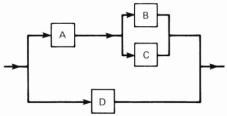

syms R        % reliability variables
syms t L Real

[RA, RB, RC, RD] = deal(R);
R_u = RA * (RB + RC - RB *RC)   % reliability of upper train

$$R\_u = R\,\left(2\,R-R^{2}\right)$$

Then, let's find the reliability of the system

R_sy = R_u + RD - R_u*RD

$$R\_sy = R-R^{2}\,\left(2\,R-R^{2}\right)+R\,\left(2\,R-R^{2}\right)$$

Now, we have-

R = exp(-L*t);

Then the sytem expression becomes-

R_sy = eval(R_sy)

$$R\_sy = {\mathrm{e}}^{-L\,t}+{\mathrm{e}}^{-L\,t}\,\left(2\,{\mathrm{e}}^{-L\,t}-{\mathrm{e}}^{-2\,L\,t}\right)-{\mathrm{e}}^{-2\,L\,t}\,\left(2\,{\mathrm{e}}^{-L\,t}-{\mathrm{e}}^{-2\,L\,t}\right)$$

Now, given-

L = 3e-5;               % hazard rate; h^-1
R_sy = eval(R_sy);      % evaluating- putting L

Then, we know, MTTF_sy-


$$MTTF_{\mathrm{sy}} =\int_0^{\infty } R\left(t\right)dt$$


MTTF_sy = int(R_sy, t, 0, inf);
MTTF_sy = double(MTTF_sy)           % hours

MTTF_sy = 4.1667e+04

## Prob-3.4

Let's tabulate different states and probabilities like this-

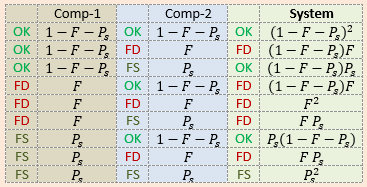

syms P_s F
P_ok = (1 - F - P_s)^2 + 2*(1 - F - P_s)*P_s;   % success
P_ok = simplify(P_ok)

$$P\_ok = F^{2}-2\,F-{P_{s}}^{2}+1$$

Then we have

P_fd = 2*(1 - F - P_s)*F + F^2 + 2*F*P_s;       % fail danger
P_fd = simplify(P_fd)

$$P\_fd = -F\,\left(F-2\right)$$

Now, from RSANS equation 4.14, we have-

Let's verify it-

N = 2; M = 2;
P_fd = 0;           % initialize
for n = 0:1: M-1
        C = nchoosek(N,n);
    P_fd_n = C * F^(N-n) *(1-F)^n;
    P_fd = P_fd + P_fd_n;
end 
P_fd = simplify(P_fd)

$$P\_fd = -F\,\left(F-2\right)$$

So, RSANS equation 4.14 is verified here.

Again, we have-

P_fs = P_s^2                        % fail safe

$$P\_fs = {P_{s}}^{2}$$

From RSANS equation 4.16, we have-

Now, let's verify

N = 2; M = 2;
P_fs = 0;           % initialize
for n = M:1: N
        C = nchoosek(N,n);
    P_fs_n = C * P_s^n *(1-P_s)^(N-n);
    P_fs = P_fs + P_fs_n;
end 
P_fs = simplify(P_fs)

$$P\_fs = {P_{s}}^{2}$$

So, RSANS equation 4.14 is verified here.